# **复制路径规划所用代码**

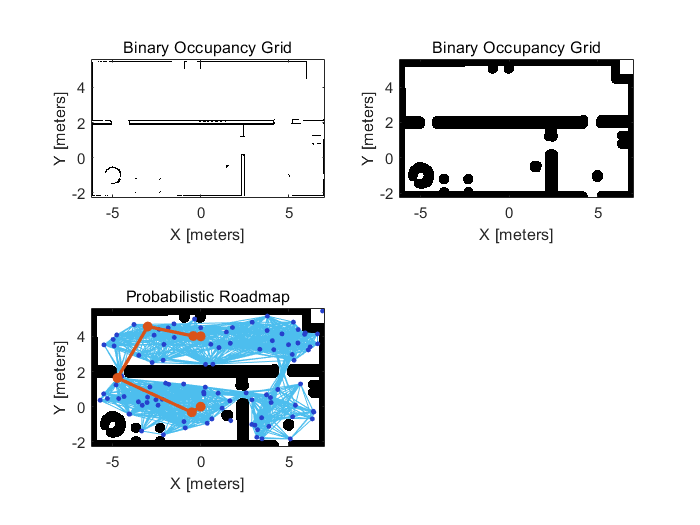

clear;close all;clc;

load("officemap.mat");
figure(1)
subplot(2,2,1);
show(map);

robotRadius=0.25;
mapInflated=copy(map);
inflate(mapInflated,robotRadius);
subplot(2,2,2);
show(mapInflated);

prm=mobileRobotPRM(mapInflated);
prm.NumNodes=100;
prm.ConnectionDistance=5;

startLocation = [0 0];
endLocation = [0 4];

path=findpath(prm, startLocation, endLocation);
subplot(2,2,3);
show(prm);

# **定义机器人的初始和目标位置**

robotCurrentLocation = [0.02 -0.05];    % 加入偏差
robotGoal = path(end,:);

# **定义机器人的初始朝向**

initialOrientation = 0.01;              % 加入偏差

# **定义机器人的当前位姿**

robotCurrentPose = [robotCurrentLocation initialOrientation];

# **创建差动机器人**

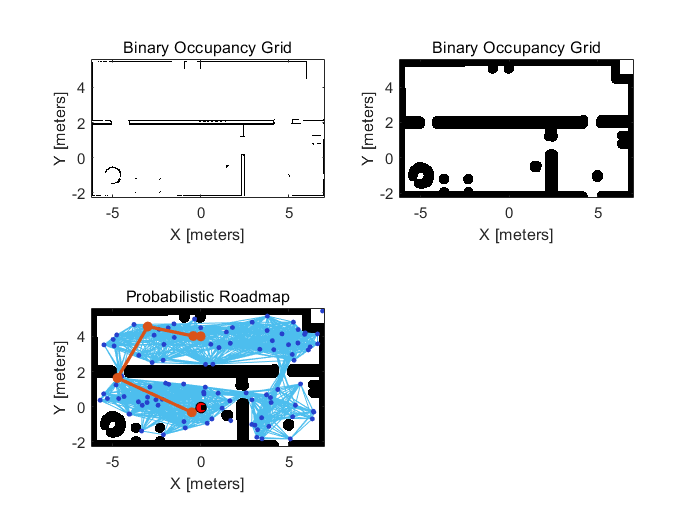

robot = ExampleHelperDifferentialDriveRobot(robotCurrentPose);

# **创建控制器（纯追踪算法）**

controller = controllerPurePursuit;      % 创建算法
controller.Waypoints = path;             % 设置参数
controller.DesiredLinearVelocity = 0.3; 
controller.MaxAngularVelocity = 3;
controller.LookaheadDistance = 0.5;

# ** 定义目标半径和初始偏差**

goalRadius=0.05;
distanceToGoal=norm(robotCurrentLocation - robotGoal);

# **运动控制**

while( distanceToGoal > goalRadius )

[v2,omega2]=step(controller, robot.CurrentPose);           % 根据当前Pose，计算速度和转角

drive(robot,v2,omega2);                                    % 驱动机器人

robotCurrentLocation = robot.CurrentPose(1:2);             % 获取驱动后Pose 
distanceToGoal = norm(robotCurrentLocation - robotGoal);   % 计算偏差

waitfor(rateControl(20));                                  % 延迟等待
end

您需要 MATLAB Coder Support Package for NVIDIA Jetson and NVIDIA DRIVE Platforms 支持包才能使用此功能。请打开附加功能资源管理器以安装所需的支持包。